Section 1

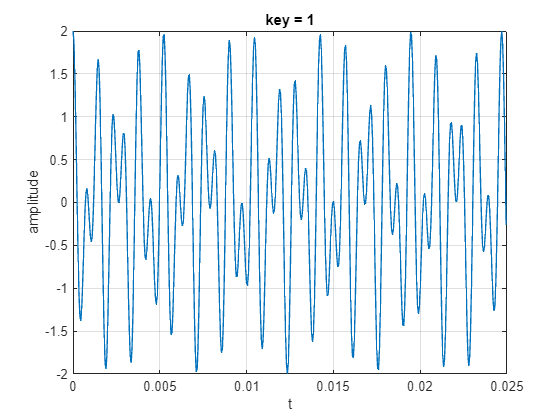

init();
N = 10000; %number of samples in time and freq domain
T = 0.5; % Signal period
Ts = T/N; %sample period
Fs = 1/Ts; %Sample rate
t=0:Ts:T-Ts;
ind=0:(N-1);
% DTMF for '1'
%f1 = 852; 
f1 = 770;
f2 = 1336;
y1 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
make_plot(t(1:500),y1(1:500),'key = 1','t','amplitude')

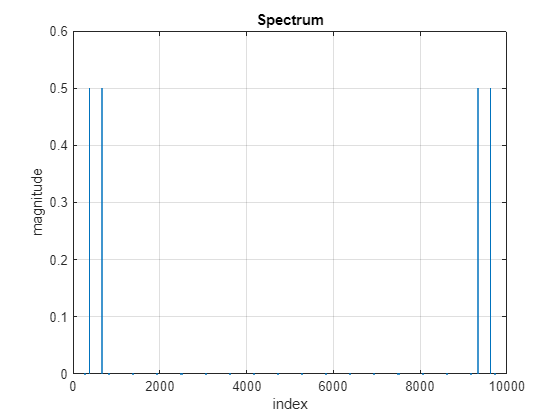

% compute cm
cm_key1 = fft(y1)/N;
make_plot(ind,abs(cm_key1),'Spectrum','index','magnitude')

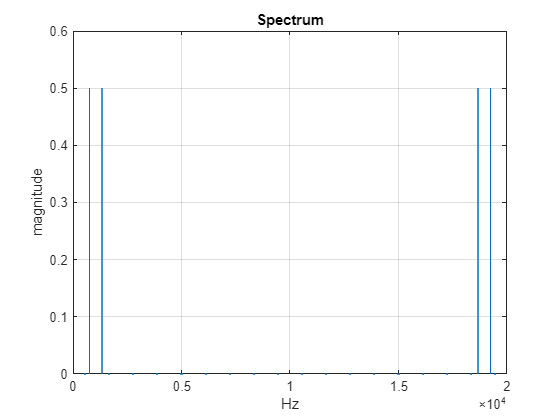

f_hz = (ind)/N*Fs; % x-axis
make_plot(f_hz,abs(cm_key1),'Spectrum','Hz','magnitude')

Section 2

init();
N = 10000; %number of samples in time and freq domain
T = 0.5; % Signal period
Ts = T/N; %sample period
Fs = 1/Ts; %Sample rate
t=0:Ts:T-Ts;
% DTMF for '1'
f1 = 697;
f2 = 1209;
y1 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
% DTMF for '2'
f1 =697;
f2 = 1336;
y2 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
% DTMF for '3'
f1 = 697;
f2 = 1477;
y3 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
% DTMF for '4'
f1 = 697;
f2 = 1633;
y4 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
sound(y1,Fs);
pause(0.6);
sound(y2,Fs);
pause(0.6);
sound(y3,Fs);
pause(0.6);
sound(y4,Fs);

Section 3

init();
N = 10000; %number of samples in time and freq domain
T = 0.5; % Signal period
Ts = T/N; %sample period
Fs = 1/Ts; %Sample rate
t=0:Ts:T-Ts;
% DTMF for '1'
f1 = 697;
f2 = 1209;
y1 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
% DTMF for '5'
f1 =770;
f2 =1336;
y5 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
% DTMF for '9'
f1 = 852;
f2 = 1477;
y9 = cos (2*pi*f1*t) + cos(2*pi*f2*t);
findpeaks(y1);

freqs =          696        1210       18790       19304


key pressed:1


findpeaks(y5);

freqs =          770        1336       18664       19230


key pressed:5


findpeaks(y9);

freqs = 1.0e+04 *

    0.0852    0.1478    1.8522    1.9148


key pressed:9
